## Visualización de Datos

Creemos los datos que nos servirán para realizar los ejemplos y guardémoslo en un archivo:

matrizDatos=randi(100, 100);
save ../data/matrizDatos matrizDatos

Creemos los datos que nos servirán para realizar los ejemplos:

A = struct2mat(load("../data/matrizDatos"))

matriz =     21    80    55    34    89    41    98    54    70    95    83    51    37    92    31   100    16     3    11    23    25    48    83    58    76    34    26     7    46    91    95    83    79    53    21    46    93    38     5   100    43    32    99    91    19    93    14     7    88    62
    64    25    40    33    83     6     2    49    89    47    92    81    29    32    15    53    96    52    71    80    11    19    71    35    17    94    62    10    92    95    59    79    64    49    70    31    44    37    46    45    17    11    88    79    76     9    10    90    79    69
    28    36    84     1    38    67    25    13    53    20    94    87    79    36    53    68   100    12    12    53     2    35    36    74    98    57    70    46    83    39    46    77    11    36    89    98    87    63    78     8    87    31    45    26    30    39    86    77    70   100
    34    66    57     3    54    60    41     8    93    57    31    76    53    23    

A =     21    80    55    34    89    41    98    54    70    95    83    51    37    92    31   100    16     3    11    23    25    48    83    58    76    34    26     7    46    91    95    83    79    53    21    46    93    38     5   100    43    32    99    91    19    93    14     7    88    62
    64    25    40    33    83     6     2    49    89    47    92    81    29    32    15    53    96    52    71    80    11    19    71    35    17    94    62    10    92    95    59    79    64    49    70    31    44    37    46    45    17    11    88    79    76     9    10    90    79    69
    28    36    84     1    38    67    25    13    53    20    94    87    79    36    53    68   100    12    12    53     2    35    36    74    98    57    70    46    83    39    46    77    11    36    89    98    87    63    78     8    87    31    45    26    30    39    86    77    70   100
    34    66    57     3    54    60    41     8    93    57    31    76    53    23    14   

B=flipud(A);
C=fliplr(A);
D=rot90(A);
E=A';
F=A(:);

Ahora creemos nuestra primera gráfica utilizando la función `imgesc(A)`: esta muestra los datos del arreglo A como una imagen que usa la gama completa de colores del mapa de colores. Cada elemento de A especifica el color de un píxel de la imagen. La imagen resultante es una cuadrícula de píxeles de `m` por `n` donde `m` es el número de filas y `n` es el número de columnas de A. Los índices de fila y de columna de los elementos determinan los centros de los píxeles correspondientes. Veamos un ejemplo:

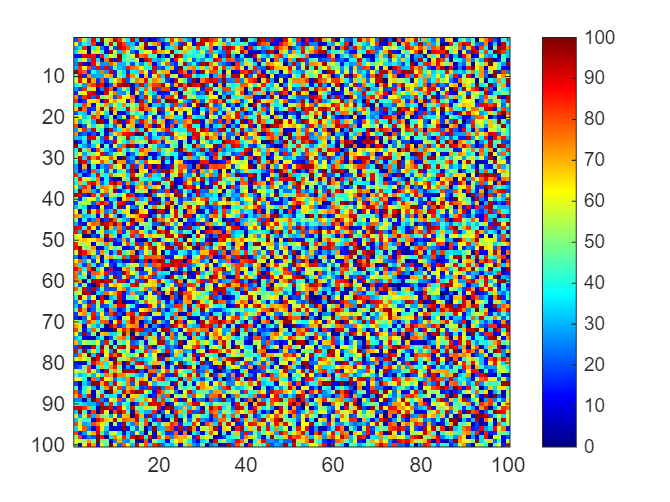

imagesc(A); clim([0 100]); colormap jet; colorbar

 Distintas escalas de `colormap` se pueden encontrar en este [enlace](https://la.mathworks.com/help/matlab/ref/colormap.html?s_tid=doc_ta). Ahora usemos el comando `subplot(m,n,p)`: divide la figura actual en una cuadrícula de `m` por `n` y crea ejes en la posición que especifica `p`. MATLAB® numera las posiciones de subgráfica por fila. La primera subgráfica es  la primera columna de la primera fila, la segunda subgráfica es la  segunda columna de la primera fila y así sucesivamente. Si hay ejes en  la posición especificada, este comando convierte los ejes en los ejes  actuales.

figure % crea una ventana de figura nueva utilizando valores de propiedades predeterminados.
subplot(2,3,1)
imagesc(A); clim([0 100]); colormap jet; colorbar
title('matriz A')
ylabel('valor en y')

Agreguemos otra figura:

subplot(2,3,2)
imagesc(B); clim([0 100]); colormap jet; colorbar
title('flipud(A)')

Y adjuntemos algunas más:

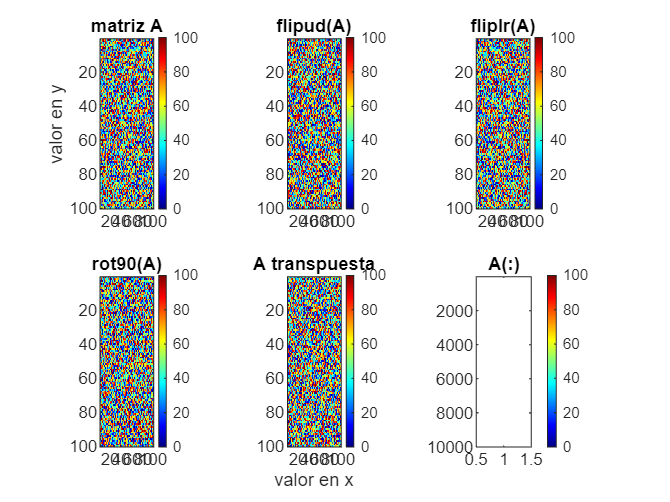

subplot(2,3,3)
imagesc(C); caxis([0 100]); colormap jet; colorbar
title('fliplr(A)')
subplot(2,3,4)
imagesc(D); caxis([0 100]); colormap jet; colorbar
title('rot90(A)')
subplot(2,3,5)
imagesc(E); caxis([0 100]); colormap jet; colorbar
title('A transpuesta')
xlabel('valor en x')
subplot(2,3,6)
imagesc(F); caxis([0 100]); colormap jet; colorbar
title('A(:)')

Con la función `pcolor(A)` se puede crear otro tipo de gráfica: crea un gráfico de pseudocolores utilizando los valores de la matriz C. Un gráfico de pseudocolores muestra los datos de la matriz como un arreglo de celdas coloreadas (conocidas como caras).

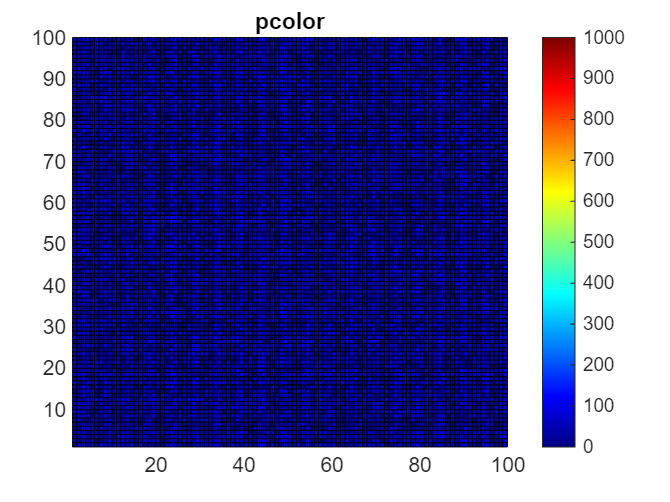

figure
pcolor(A); clim([0 1000]); colormap jet; colorbar
title('pcolor')
shading flat
shading faceted

Generar una figra 2D con `plot(X,Y)`.  Primero creemos los datos para los ejemplos:

X=0:0.01:30; b=1;
Y=0.45*X+b;
Y2=3.*sin(2*pi/3*X);
Y3=Y2.*exp(0.5*X);

Grafiquemos lo siguientes:

figure
plot(X,Y,':')
hold on

Agreguemos la siguiente gráfica:

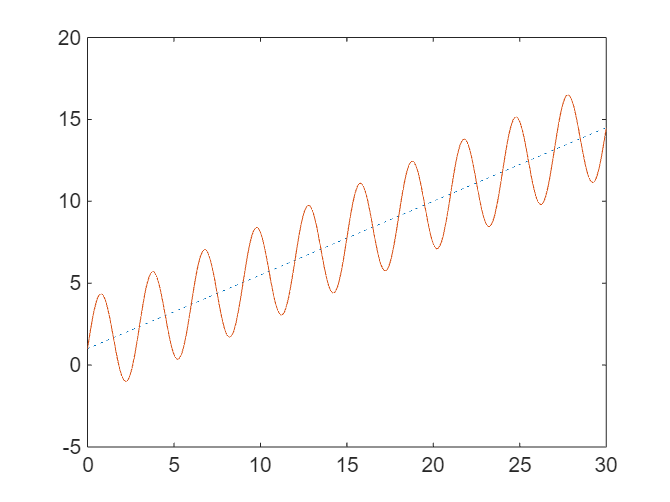

plot(X,Y2+Y)

Veamos otro ejemplo:

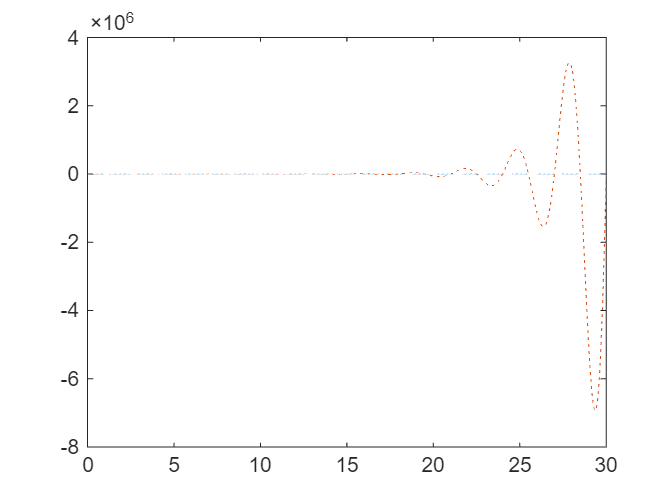

figure
plot(X,Y,'--',X,Y3,':')

Exploremos otras opciones que podemos usar con la función `plot`:

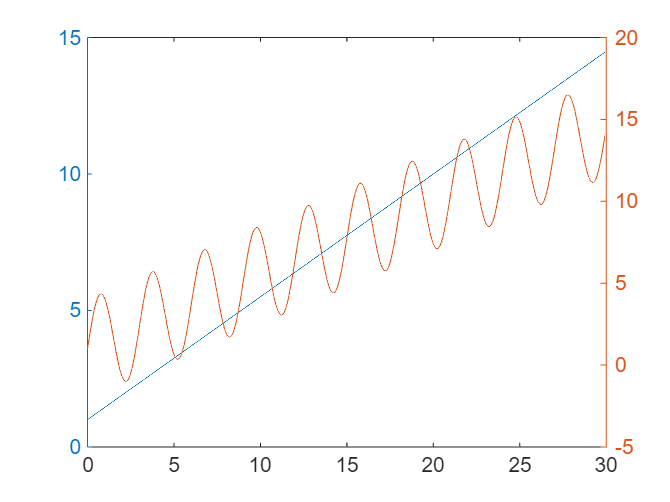

figure
yyaxis left
plot(X,Y)
yyaxis right
plot(X,Y2+Y)

Analicemos este ejemplo:

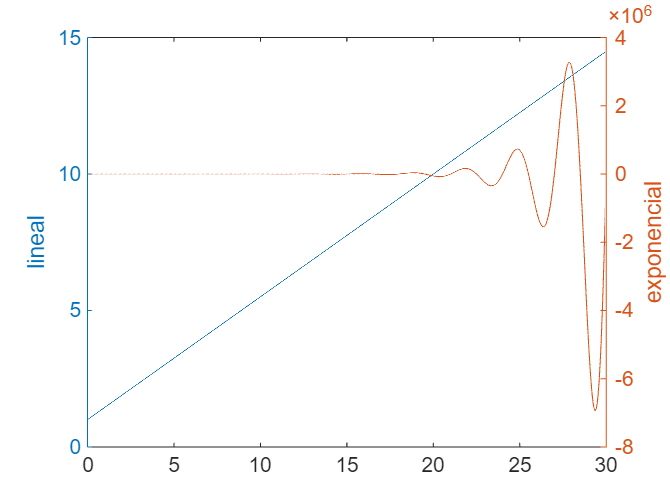

figure
yyaxis left
plot(X,Y)
ylabel('lineal')
yyaxis right
plot(X,Y3)
ylabel('exponencial')